# RLSによる離散時間状態予測

## 状態方程式の宣言

clear all

m = 1;
l = 1;
I = 0;
c = 0;
g = 9.81;

A = [0 1; -m*g*l/(I+m*l^2) -c/(I+m*l^2)];
B = [0; 1/(I+m*l^2)];
C = eye(2);

sys = ss(A, B, C, []);
sysd = c2d(sys, 0.05);
Ad = sysd.A;
Bd = sysd.B;

## 状態予測器の構成

initialParameter = -0.05 + (0.05+0.05) * rand(size(A, 2)+size(B, 2), size(A, 1));
initialCovariance = eye(size(A, 2)+size(B, 2)) * 10;

statePredictor = MultivariableRecursiveLS(3, 2, "initialParameter", initialParameter, "initialCovariance", initialCovariance, "ForgettingFactor", 1);
statePredictor = MultivariableRecursiveLS(3, 2);

## 状態の予測

x = [0; 0];

for i = 1 : 300
    u = -1 + 2 * rand(size(B, 2));
    ulist(i) = u;
    dx = Ad * x + B * u;
    [theta, dxHat] = statePredictor.step(dx, [x;u]);
    err(i) = norm(dx-dxHat);
    x = dx;
end

## 誤差の推移

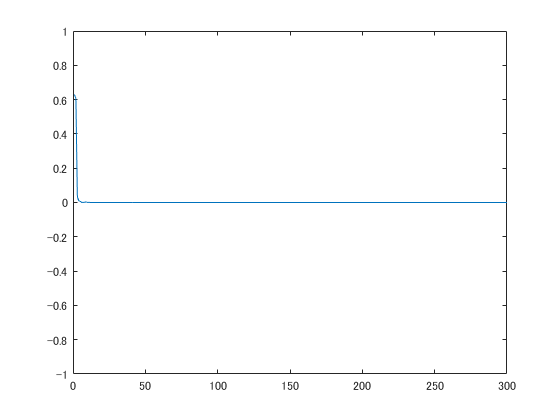

plot(err)
ylim([-1 1])